# ECG Analysis

Example shows peak analysis in an ECG 

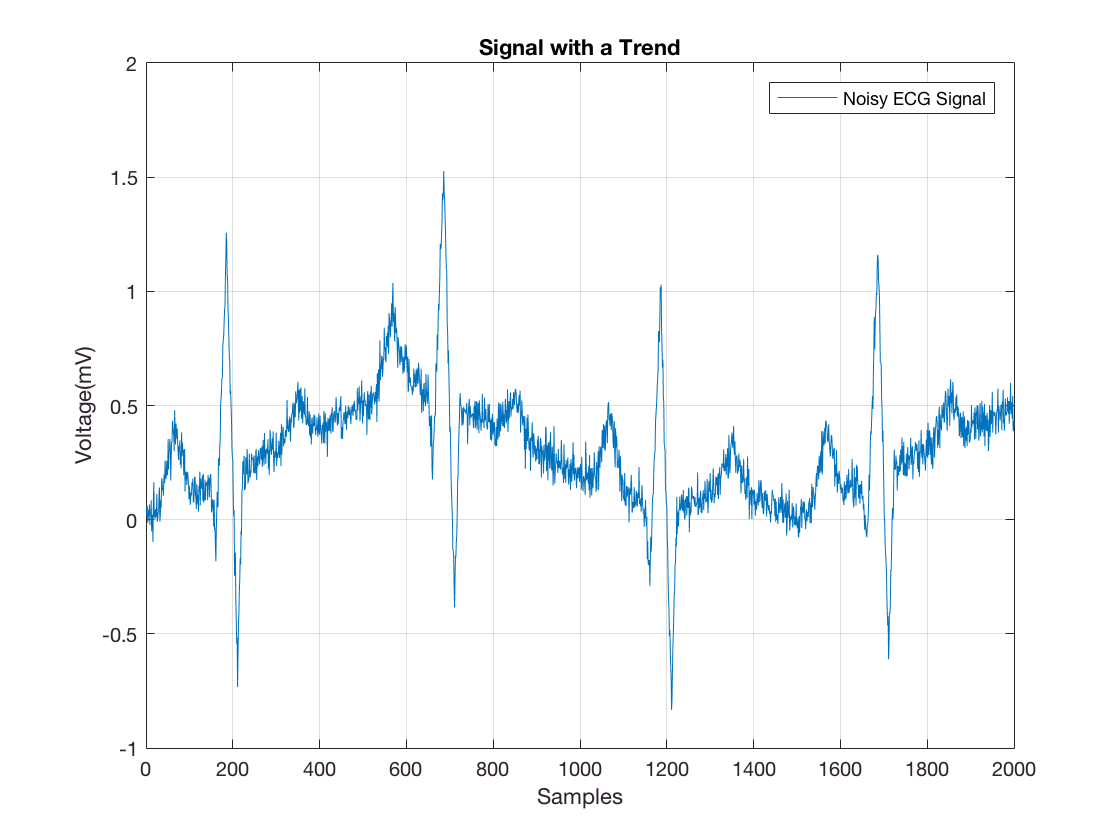

load noisyecg.mat
t = 1:length(noisyECG_withTrend);
figure
plot(t,noisyECG_withTrend)
title('Signal with a Trend')
xlabel('Samples');
ylabel('Voltage(mV)')
legend('Noisy ECG Signal')
grid on

## Detrending data

Above signal shows a baseline shift and therefore does not represent the true amplitude

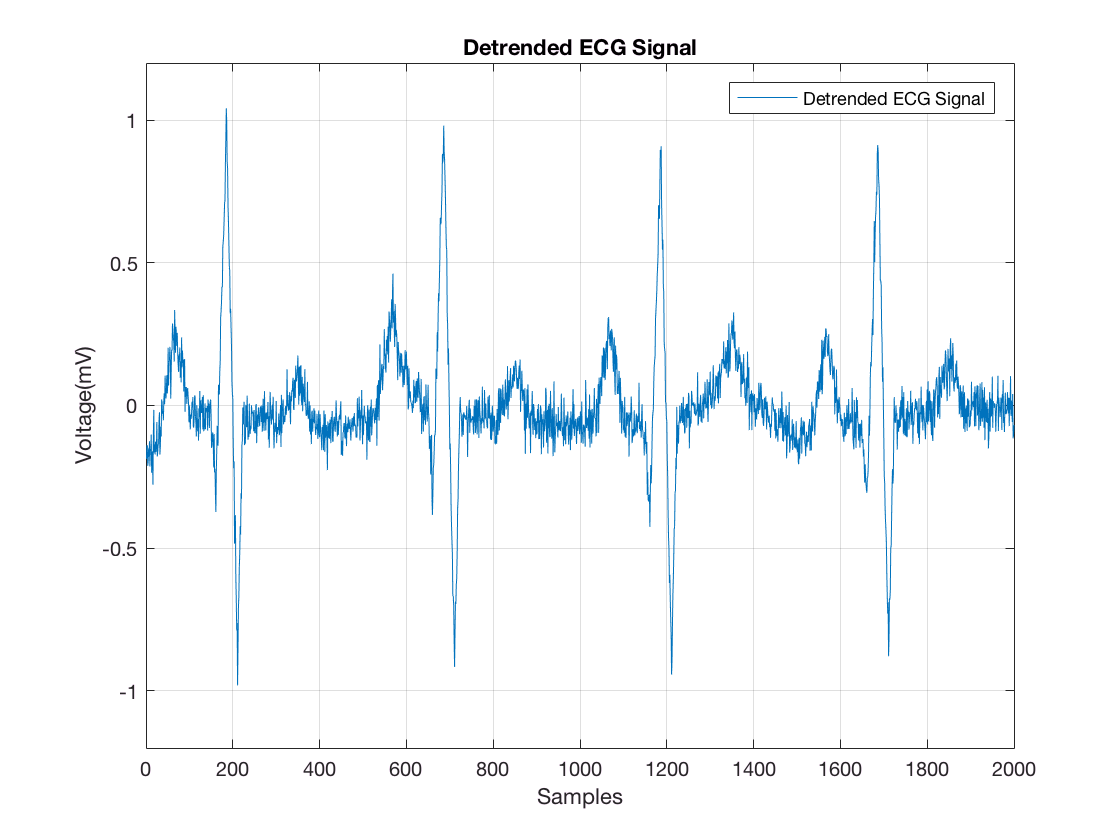

[p,s,mu] = polyfit((1:numel(noisyECG_withTrend))',noisyECG_withTrend,6);
f_y = polyval(p,(1:numel(noisyECG_withTrend))',[],mu);

ECG_data = noisyECG_withTrend - f_y;        % Detrend data

figure
plot(t,ECG_data); grid on
ax = axis; axis([ax(1:2) -1.2 1.2])
title('Detrended ECG Signal')
xlabel('Samples'); ylabel('Voltage(mV)')
legend('Detrended ECG Signal')

## Thresholding to find Peak of Interst

QRS-complex consists of three major components: Q-wave, R-wave, S-wave R-waves can be detected by thresholding peaks above 0.5mV Notice that the R-waves are separated by more than 200 samples

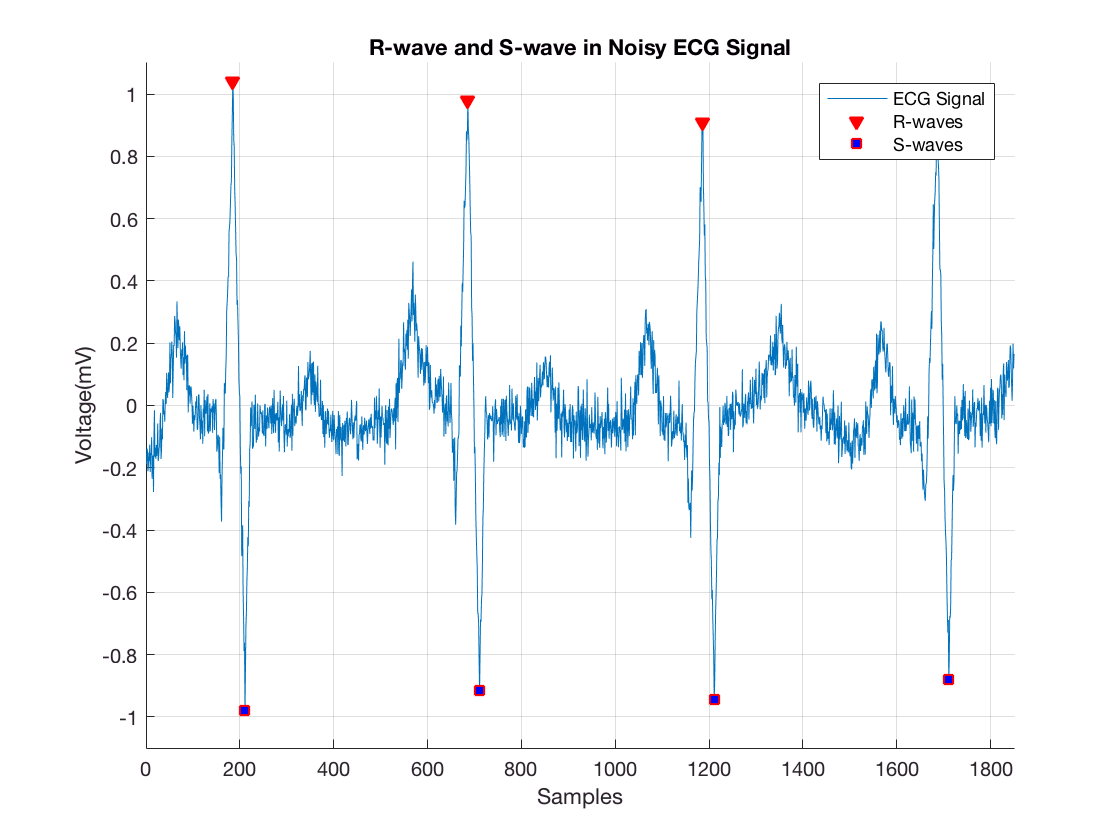

[~,locs_Rwave] = findpeaks(ECG_data,'MinPeakHeight',0.5,'MinPeakDistance',200);

% For detection of the S-waves, find the local minima in the signal and 
% apply thresholds appropriately

ECG_inverted = -ECG_data;
[~,locs_Swave] = findpeaks(ECG_inverted,'MinPeakHeight',0.5,'MinPeakDistance',200);

%  Plot shows the R-waves and S-waves detected in the signal
figure
hold on
plot(t,ECG_data);
plot(locs_Rwave,ECG_data(locs_Rwave),'rv','MarkerFaceColor','r');
plot(locs_Swave,ECG_data(locs_Swave),'rs','MarkerFaceColor','b');
axis([0 1850 -1.1 1.1]); grid on;
legend('ECG Signal','R-waves','S-waves');
xlabel('Samples'); ylabel('Voltage(mV)')
title('R-wave and S-wave in Noisy ECG Signal')

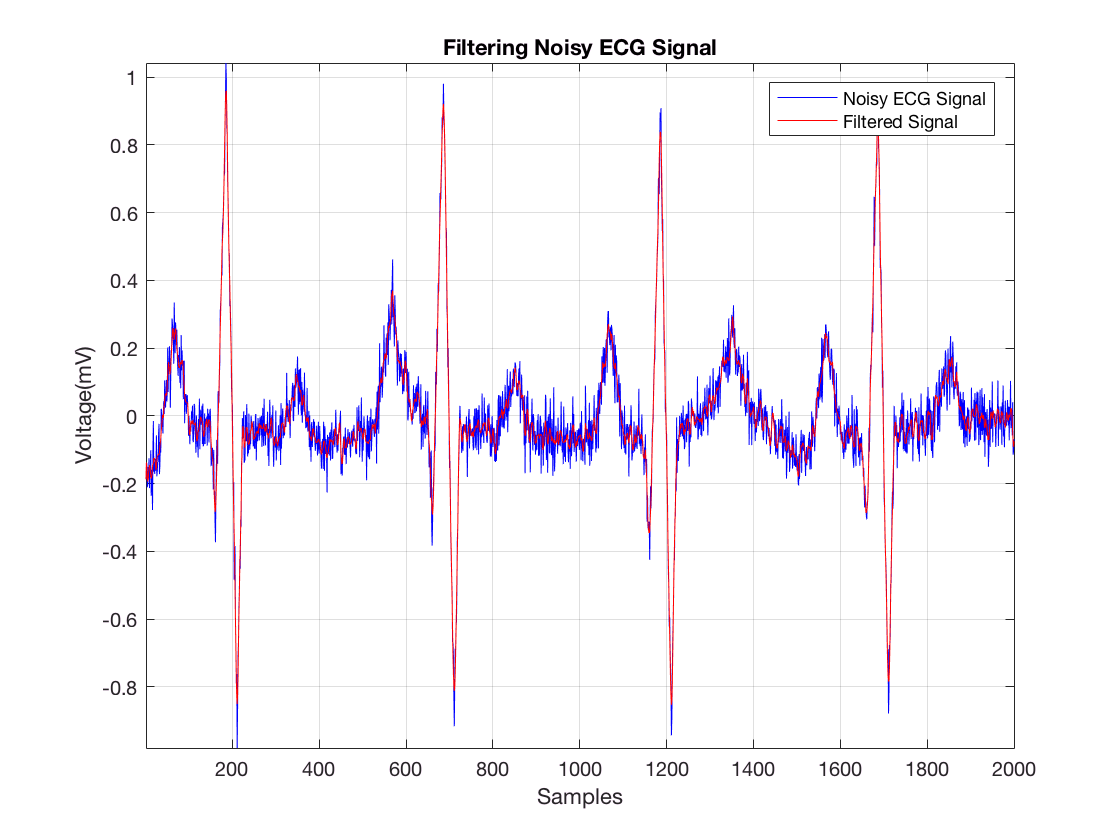


% Thresholding the peaks to locate the Q-waves results in detection of 
% unwanted peaks as the Q-waves are buried in noise

smoothECG = sgolayfilt(ECG_data,7,21);

figure
plot(t,ECG_data,'b',t,smoothECG,'r'); grid on
axis tight;
xlabel('Samples'); ylabel('Voltage(mV)');
legend('Noisy ECG Signal','Filtered Signal')
title('Filtering Noisy ECG Signal')

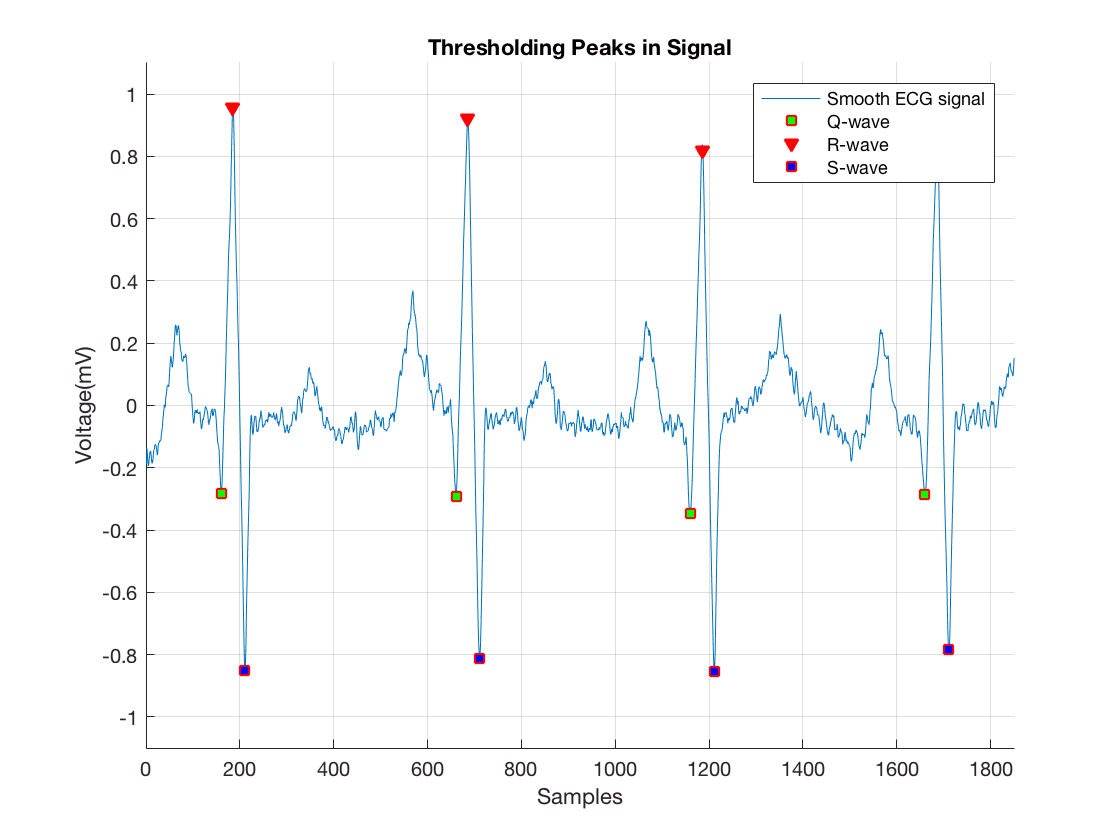



% perform peak detection on the smooth signal and use logical indexing
% to find the locations of the Q-waves


[~,min_locs] = findpeaks(-smoothECG,'MinPeakDistance',40);

% Peaks between -0.2mV and -0.5mV
locs_Qwave = min_locs(smoothECG(min_locs)>-0.5 & smoothECG(min_locs)<-0.2);

figure
hold on
plot(t,smoothECG);
plot(locs_Qwave,smoothECG(locs_Qwave),'rs','MarkerFaceColor','g');
plot(locs_Rwave,smoothECG(locs_Rwave),'rv','MarkerFaceColor','r');
plot(locs_Swave,smoothECG(locs_Swave),'rs','MarkerFaceColor','b');
grid on
title('Thresholding Peaks in Signal')
xlabel('Samples'); ylabel('Voltage(mV)')
ax = axis; axis([0 1850 -1.1 1.1])
legend('Smooth ECG signal','Q-wave','R-wave','S-wave');

## Error Analysis

Notice the average difference between the QRS-complex in the raw and the detrended filtered signal.

% Values of the Extrema
[val_Qwave, val_Rwave, val_Swave] = deal(smoothECG(locs_Qwave),smoothECG(locs_Rwave),smoothECG(locs_Swave));
meanError_Qwave = mean((noisyECG_withTrend(locs_Qwave) - val_Qwave));
meanError_Rwave = mean((noisyECG_withTrend(locs_Rwave) - val_Rwave));
meanError_Swave = mean((noisyECG_withTrend(locs_Swave) - val_Swave));

## Peak Properties

Some important peak properties involve rise time, fall time, rise level, and fall level

avg_riseTime = mean(locs_Rwave-locs_Qwave); % Average Rise time
avg_fallTime = mean(locs_Swave-locs_Rwave); % Average Fall time
avg_riseLevel = mean(val_Rwave-val_Qwave);  % Average Rise Level
avg_fallLevel = mean(val_Rwave-val_Swave);  % Average Fall Level

helperPeakAnalysisPlot(t,smoothECG,locs_Qwave,locs_Rwave,locs_Swave,...
   val_Qwave,val_Rwave,val_Swave,avg_riseTime,avg_fallTime,...
   avg_riseLevel,avg_fallLevel)